# Introducción a las funciones lógicas y estructuras de control

Una forma de pensar los programas de cómputo (no sólo MATLAB) es considerar cómo se organizan los enunciados que componen el programa. Por lo general, las secciones del código de los programas de cómputo se pueden categorizar en una de tres estructuras: secuencias, estructuras de selección y estructuras de repetición.  

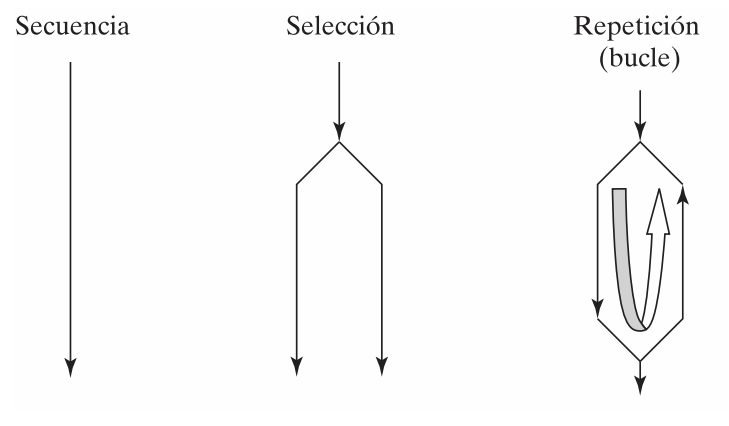

- **Secuencia:** Estructura en forma de listas de comandos que se ejecutan una después de otra de forma lineal.

- **Selección:** Estructura que permite elegir qué es lo que hará el programa, es decir, le permite seleccionar una línea de códigos u otra, pero no ambas. A estas estructuras también se les llama condicionales.

- **Repetición:** Estructura que permite repetir una línea de código cierta cantidad de veces o hasta mientras se cumpla una condición dada.

Como se podrá notar, hasta este momento únicamente se ha trabajado con las secuencias. A partir de ahora se empezará a trabajar con las estructuras de selección y repetición.

# Operadores relacionales y lógicos

MATLAB está diseñado principalmente para ingenieros y científicos. Bajo esta premisa, todo ingeniero o científico cursó una asignatura básica de fundamentos de matemática (incluso desde la formación inicial). En esta asignatura se estudió lógica, tablas de verdad, etc.

Básicamente lo que se hará en las estructuras de control es usar esos conocimientos básicos y aplicarlos a la programación.

Con lo anterior dicho, bastará recordar cuáles son los operadores relaciones y lógicos.

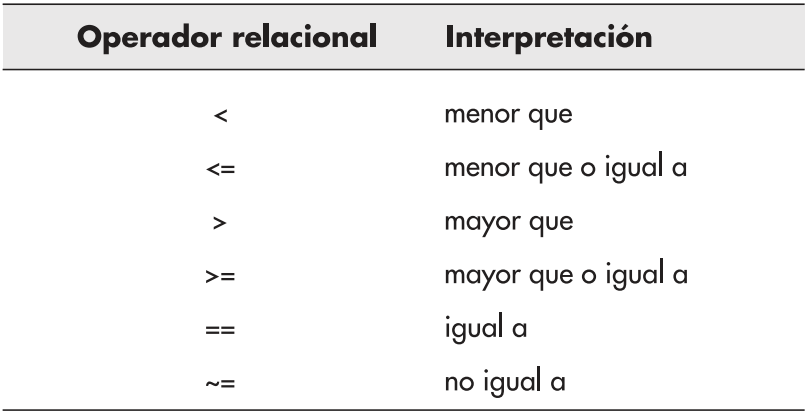

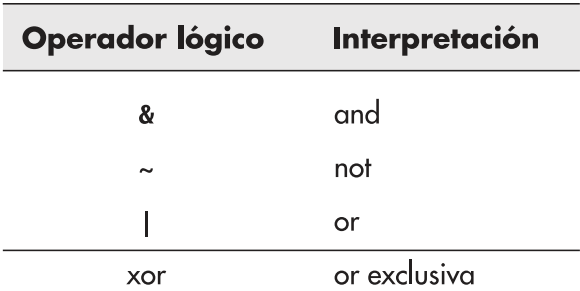

Lo único nuevo, si es que lo es, es introducir el concepto básico del Álgebra Booleana. En base a esta álgebra, sólo existen dos valores: 0 y 1. El 0 significa falso (`false`) y el 1 significa verdadero (`true`).

Así pues, lo que se hará en programación es utilizar los operadores detallados en las tablas con el álgebra de Boole.

## Ejemplo

Arturo necesita pasar la Cálculo Vectorial con mínimo 7/10, sin embargo, está preocupado porque en el primer bimestre no le fue muy bien y no sabe si alcanzará la nota mínima. Entonces Arturo platica con su profe y como él es chévere le dice que le acolitará si saca 6 o más en el examen final.

¿Cuántos casos posibles hay?

- Arturo saca 6 o más.

- Arturo saca menos de 6.

Veámoslo con código:

clear

finalTest = randi(10)  % Calificación del examen de Arturo.

finalTest >= 6         % Comparación lógica.

Utilizamos un número aleatorio entero (`randi`) entre 0 y 10 para hacer dinámico el ejercicio. (Pruebe a correr el código varias veces).

Entonces, si la calificación del examen de Arturo (`finalTest`) es mayor o igual que 6 se devolverá un `1` lógico (`true`), caso contrario se devolverá un `0` lógico (`false`).

Básicamente esto es lo que se hará en las estructuras de control: comparaciones lógicas.

Claro que se pueden hacer comparaciones más complejas añadiendo conjunciones (`y`) o disyunciones (`o`), entre otras. Sin embargo, por esta razón se hizo mención que un ingeniero o científico debe conocer cómo funcionan estas operaciones lógicas necesariamente.

Un último detalle importante es que estamos trabajando en MATLAB, es decir, en muchas ocasiones probablemente comparemos matrices. ¿Cómo comparo lógicamente una matriz con otra?

Pero recordemos cómo hemos venido trabajando hasta ahora con estas matrices. Por supuesto que podemos hacer las operaciones del Álgebra Lineal con matrices en MATLAB, sin embargo, ¿las hemos usado realmente? Es decir, si somos observadores, notaremos que en su mayoría hemos hecho operaciones término a término. Por ende, para las operaciones relacionales también se trabajará de la misma forma.

Analicemos el siguiente ejemplo:

A = [
    1 1 1
    1 1 1
    ]
B = [
    2 2 2
    3 3 3
    ]

A < B
A >= B

Como se puede observar, al realizar las comparaciones lógicas se nos devuelve un arreglo lógico de `0` y/o `1` (recordando que son `0` y `1` lógicos). (Pruebe a cambiar los elementos de las matrices **A** y **B**).

Es decir, MATLAB hace la comparación lógica término a término. Además, al igual que con el ejemplo anterior, la comparación lógica se puede hacer tan compleja como se requiera.

**Nota:** No está demás aclarar que las matrices a ser comparadas lógicamente deben ser de la misma dimensión (¿o cómo comparamos término a término de no ser así?).

# Diagramas de flujo y pseudocódigo

Los diagramas de flujo y el pseudocódigo son extremadamente sencillos (en concepto) y útiles al momento de programar.

No se hizo mención de ellos debido a que hasta ahora sólo se ha trabajado con estructuras secuenciales y no eran necesarios. Sin embargo, de aquí en adelante se recomienda sobremanera hacer uso de ellos según se crea necesario.

## Pseudocódigo

El pseudocódigo (o "casi código") básicamente es un código informal. Es decir, se trata de detallar con enunciados simples lo que queremos hacer.

### Ejemplo

Quiero un programa simple que me calcule el producto de dos números.

El pseudocódigo podría ser:

- Inicio.

- Ingresar dos números.

- Multiplicar los números.

- Imprimir el resultado.

- Fin.

Una vez se tiene el pseudocódigo es realmente sencillo ir a escribir código siguiendo lo que hemos dicho en él.

clear

n1 = 3;             % Ingreso los números.
n2 = 5;

product = n1*n2;    % Realizo su multiplicación.

disp(result)        % Despliego el resultado.

En realidad el pseudocódigo no responde a normas establecidas ni estándares. Sin embargo, se pueden realizar algunas recomendaciones para su realización:

- Debe iniciar con un *inicio* y terminar con un *fin* porque el programa simple debe iniciar y terminar, respectivamente.

- Debe ser ordenado.

- Debe ser entendible para cualquier persona (incluso las que no programan).

- La primera palabra debe ser un verbo en infinitivo.

Como comentario personal, se puede decir que un pseudocódigo es lo mismo que un algoritmo. Claro que técnicamente no son lo mismo, sin embargo, indagando un poco se notará que no existencia una diferencia abismal entre uno y otro.

**Nota:** Un algoritmo básicamente es una receta de cocina: una secuencia de pasos ordenados y finitos que ayuda a hacer algo determinado. (En el caso de una receta de cocina ayuda a cocinar, en especial para quienes no sabemos **:(**).

## Diagramas de flujo

Si se entendió lo que es un pseudocódigo, o algoritmo, se entenderá fácilmente lo que es un diagrama de flujo: un pseudocódigo gráfico.

Es decir, en lugar de escribir lo que se quiere hacer, se va a dibujarlo. Sin embargo, en este caso si existen estándares respecto a las figuras y la forma de hacer el diagrama.

A continuación se muestra las figuras básicas: 

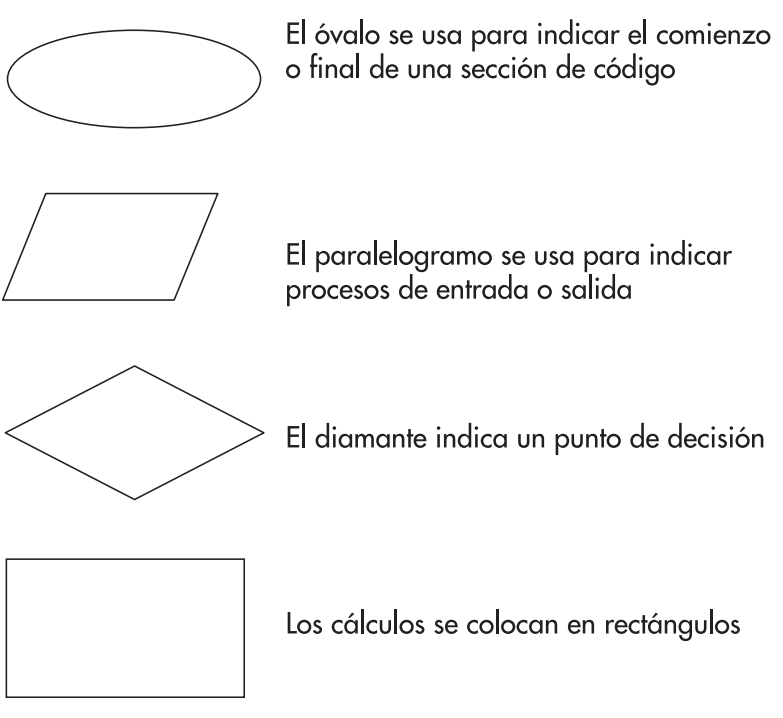

Aunque dependiendo de la fuente algunas figuras pueden cambiar ligeramente, en esencia lo que se busca es lo mismo: dibujar el algoritmo.

Las siguientes figuras fueron obtenidas de Wikipedia:

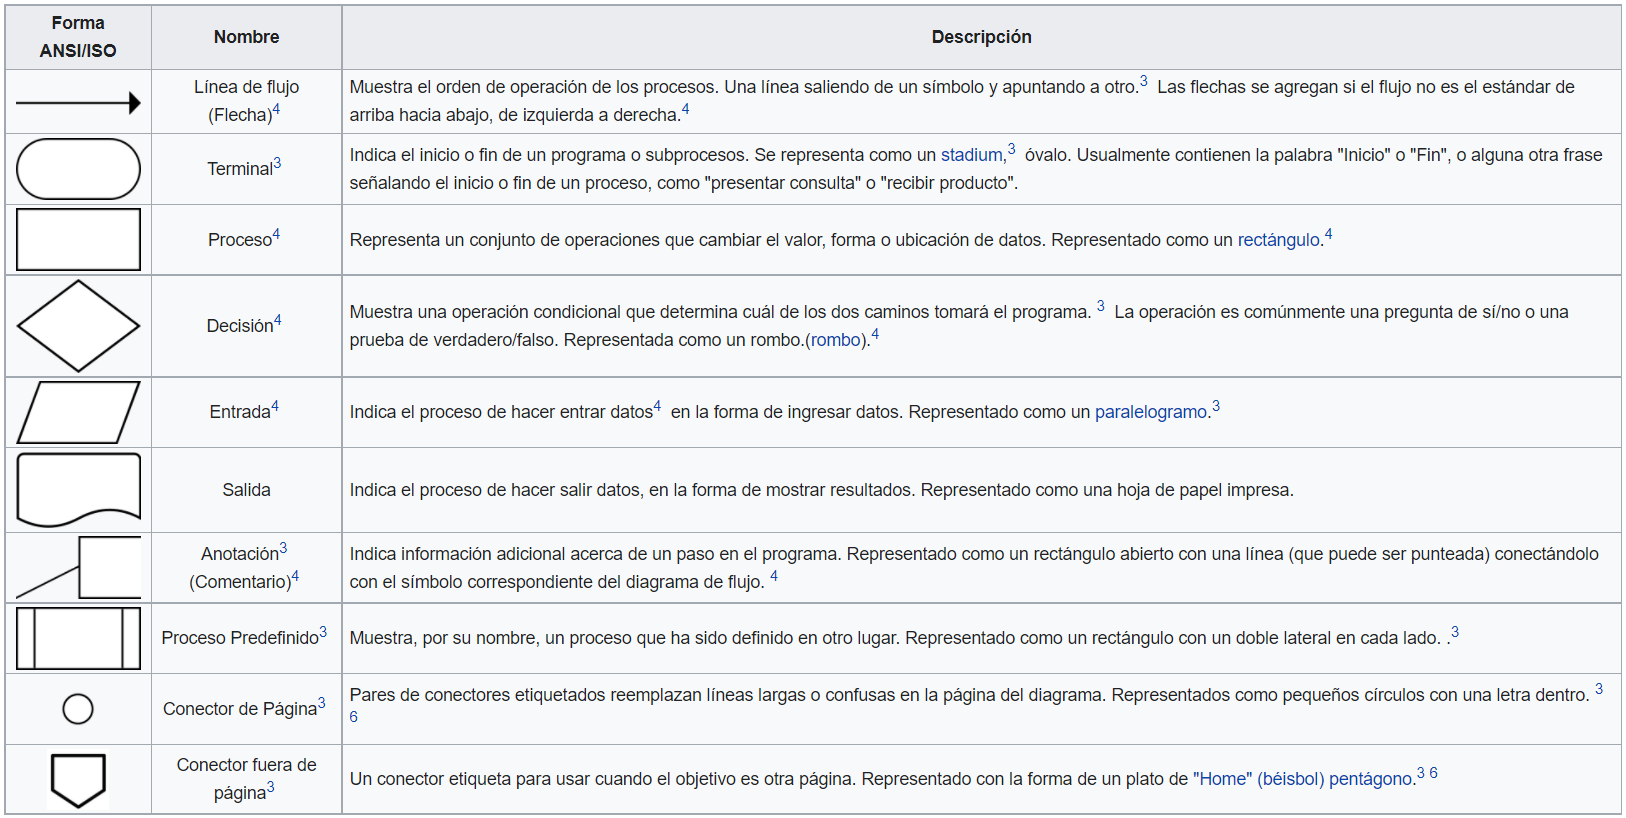

### Ejemplo

Retomando el ejemplo del pseudocódigo tenemos:

- Inicio.

- Ingresar dos números.

- Multiplicar los números.

- Imprimir el resultado.

- Fin.

Y si diagrama de flujo podría ser:

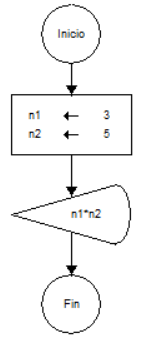

Se dice "podría ser" porque no es el único diagrama de flujo. Pudo haberse puesto dos rectángulos: uno para la variable `n1` y otro para la variable `n2`, entre otros diagramas. La idea fundamental es entender que un diagrama de flujo es la representación gráfica del pseudocódigo (o algoritmo).

Además, también se observa en el diagrama de flujo que se utilizó un cono horizontal para el despliegue del resultado en lugar del paralelogramo mencionado en la tabla de arriba.

Bien, esto se debe a la nomenclatura. Como se mencionó, dependiendo la fuente consultada es probable que varíe una que otra figura. En este caso se utilizó el programa libre DFD para la realización del diagrama de flujo mostrado y en este programa el despligue de información es el cono horizontal.

## Ejemplo con pseudocódigo y diagrama de flujo

Antes de realizar el siguiente ejemplo, es probable que alguien se pregunte ¿para qué tanto lío con el pseudocódigo o diagramas de flujo si a la final no se está programando?

Pues bien, en realidad tener un "borrador" tanto escrito como gráfico de lo que se quiere hacer puede facilitar la visualización del problema y ahorrar tiempo antes de estar con el "prueba y error".

Por supuesto que con la experiencia quizá no sea necesario realizar esto, sin embargo, considerar estas herramientas en caso de tener dificultad con un problema puede marcar la diferencia. Y para quienes recién aprenden a programar les facilita considerablemente la visualización de casi cualquier problema.

Entonces empecemos con el ejemplo, aunque en realidad vamos a retomar caso de Arturo.

El pseudocódigo para el problema planteado podría ser (revisar la parte de *Operadores relacionales y lógicos*):

- Inicio.

- Imprimir un mensaje solicitando la nota final de Arturo.

- Ingresar la nota final de Arturo.

- Comparar la nota final de Arturo.

- Si Arturo sacó 6 o más imprimir que aprueba con una carita feliz.

- Si Arturo sacó menos de 6 imprimir que repetirá la materia con una carita triste.

- Fin.

Y el diagrama de flujo podría ser:

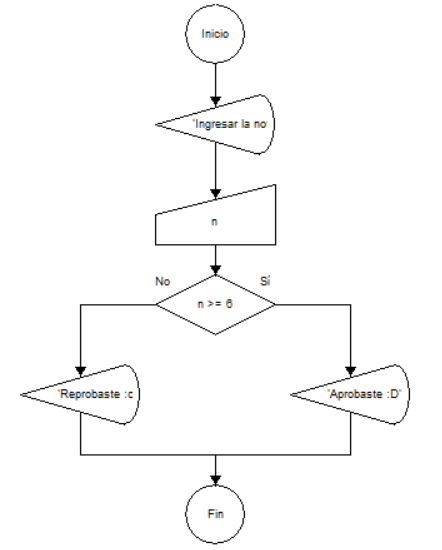

¿A que es sencillo leer y entender qué es lo que se quiere programar? Para esto sirve tanto el pseudocódigo como el diagrama de flujo. Obviamente no es necesario hacer ambos. La recomendación sería realizar el que más fácil resulte para ti entender, o si prefieres realizar ambos para una mejor comprensión también es totalmente válido. Lo importante es visualizar claramente qué se quiere hacer para luego pasar a la acción programando. 

**Nota:** Se insiste en que varían algunas figuras con respecto a las mostradas en la tabla de arriba y esto se debe a la fuente consultada. En este caso se utilizó el programa libre DFD para la realización del diagrama de flujo y en este el cono horizontal es para despliegue de información y el trapecio es para entrada de información.